# Minimum Airspeed for Takeoff vs Altitude

(Adapted from AE2440, AY24Q4, courtesy of Prof. Dobrokodov.)

Topics:

- Functions

- Logicals - using `find`

- Vector element-wise arithmetic

- 2D line ploting

In this task, you need to explore and code in MATLAB the dependency of the minimum ground speed ($V_{min}
$) for takeoff of an aircraft on the runway altitude ($h_{runway}$). 

## Models:

Here is a mathematical model for the relationship:


$$V_{\text{min}} = \sqrt{\frac{ 2 M g}{\rho(h_{runway}) \, S  \,C_L}}$$


where the air density ($\rho$) is modeled with the exponential

$\rho(h) = \rho_0 e^{-\frac{h}{H}}$.

(This is very simple model.  You don't need to understand the model, the exercise is to implement a solution with the givien model.)

Consider the nominal values for an F/A-18 Super Hornet.

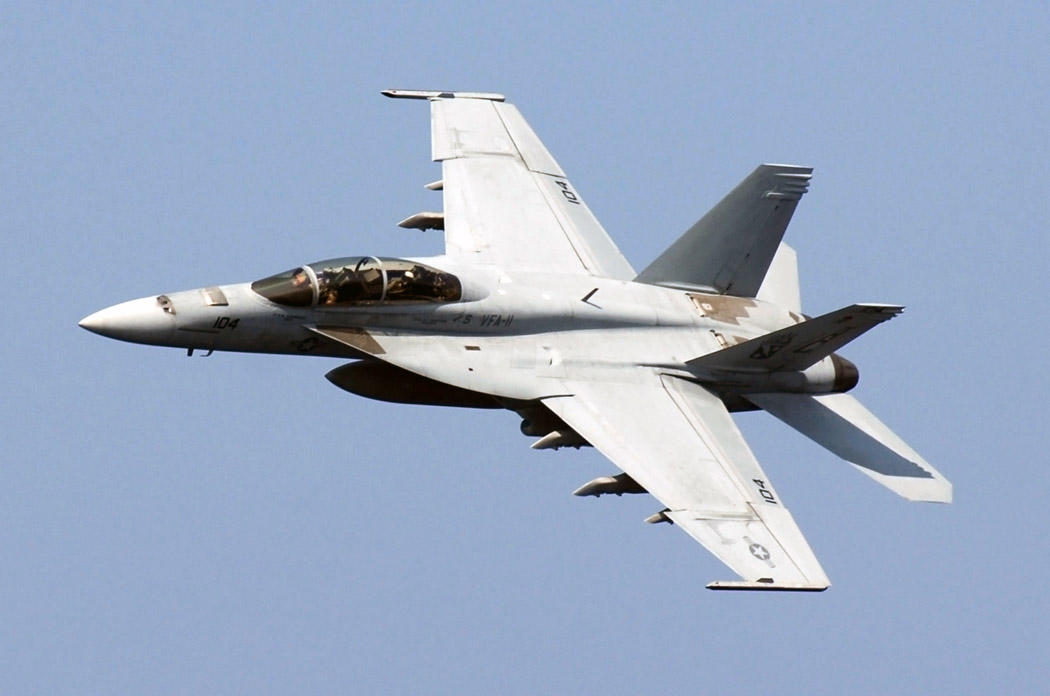

The constant coefficients are as follows:

- Lift coefficient - $C_L = 1.75$ dimensionless

- Wing surface area - $S = 37.2 \ m^2$ (per wing)

- Idealized altitude scale - $H = 8500 \ m$

- 
$$\rho_0=1.225\frac{kg}{m^3}$$


- Acceleration of gravity - $g = 9.81 \ m/s^2$

Consider two configurations for the aircraft mass

- Empty - $M = 14500 \ kg$

- Max Takeoff Weight - $M = 30000 \ kg
$

Exercises are described in the sections below

## Local functions

Write a two local functions to calculate the relationship based on the prototypes below.

Takeoff speed as a function fo altitude and aircraft mass.  Here is a prototype that you can use:

function vmin = takeoff_speed(h, m)

ans = 59.7276

    % Minimum take off speed as a function of airstrip altitude and aircraft mass.
    % Input Arguments:

ans =    59.7276   80.1509


    % - h: Runway altitude (m) [numeric, scalar or vector]
    % - m: Aircraft mass (kg) [numeric, scalar]
    % Return Variables: 
    % - vmin: Minimum takeoff speed (m/s). 
    %           Same size as `h` [numeric, scalar or vector]
    CL = 1.75;
    S = 37.2;
    g = 9.81;
    rho = density(h);
    vmin = sqrt( (2*m*g) ./ (rho*S*CL) );
end

Local function called as a sub-routine of the `takeoff_speed` function.  Again, with a prototype for you to use:

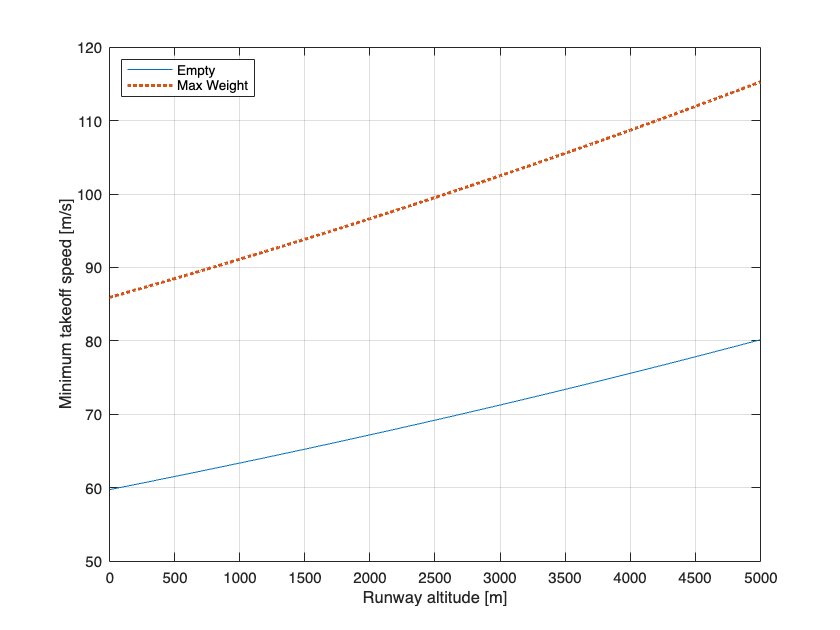

function rho = density(h)
    % Air density as a function of altitude
    % Input Arguments:
    % - h: Runway altitude (m) [numeric, scalar or vector]

    % Output Variables:
    % - rho: Air density values corresponding to the values in `h`.
    %           [numeric, scalar or vector]
    rho_o = 1.225;
    H = 8500;
    rho = rho_o * exp(-h/H);
end




Follwing incremental development, let's try this out before moving ahead.  Recall that 1 m/s ~ 2 kts.  Does it work for scalar input?

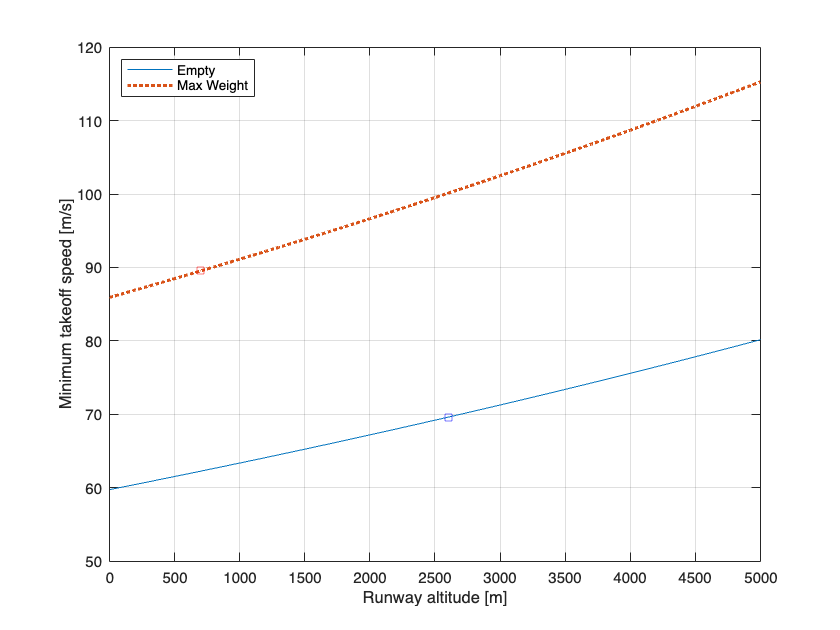

takeoff_speed(0, 14500)

How about for vector input?  We expect that as altitude increases, density decreases, so would need more ground speed to takeoff.

takeoff_speed([0 5000], 14500)

hh =            0        1000        2000        3000        4000        5000


## Plot using vectors.

Create a *well-documented* plot of the $V_{min}(h_{runway})$ for the two configurations (Empty and Max Takeoff Weight) as altitude varies 0 and 5000 m with step size of 100 m.  Use different line types, colors and line widths for the two line plots.  Inlcude a legend in a place that it doesn't obscure the information.  Include labels (with units) on the axes.

Make sure the visualization of the relationship matches your intuition; at higher altitude, would an aircraft need to go faster or slower (relative to ground, with no wind) to achieve the necessary lift for takeoff?  With more mass/weight does an aicraft need more or less ground speed to take off?

figure;

vmin_empty =    59.7276   63.3464   67.1844   71.2550   75.5722   80.1509


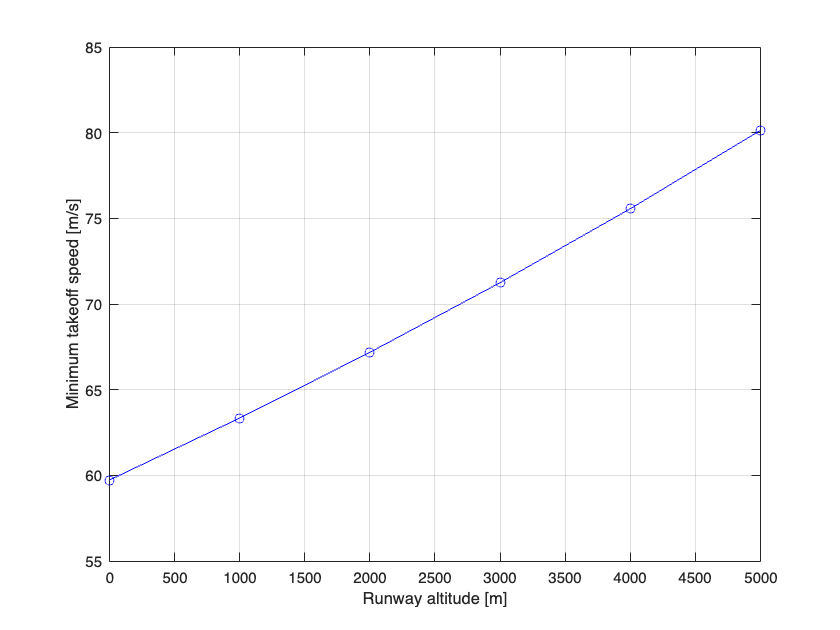

hh = 0:100:5000; % m
vmin_empty = takeoff_speed(hh, 14500);
vmin_full = takeoff_speed(hh, 30000);
p_empty = plot(hh,vmin_empty, 'DisplayName', 'Empty');
hold on
p_full = plot(hh,vmin_full,':', 'DisplayName', 'Max Weight', 'LineWidth', 2);

grid('on')
legend([p_empty p_full], 'Location', 'northwest')
xlabel('Runway altitude [m]')

ii =      1     2     3


ylabel('Minimum takeoff speed [m/s]')

## Find values

From above you should have vectors for $h_{runway}$ and $V_{min}$ of equal length.  Use the `find` function to locate the following elements in the vectors:  For an empty aircraft with a maximum speed of 70 m/s, what is the maximum runway altitude for which it can take off?  For an aircraft at max. weight that is limited to 90 m/s, what is the maximum runway altitude?  Programmatically annotate your original figure with these two points with markers. 

Finding values in two equal sized arrays,  Find the indexes corresponding to the condition. 

ii = find(vmin_empty <= 70);

ans = 67.1844

plot(hh(ii(end)), vmin_empty(ii(end)),'bs')
jj = find(vmin_full<=90);

ans = 2000

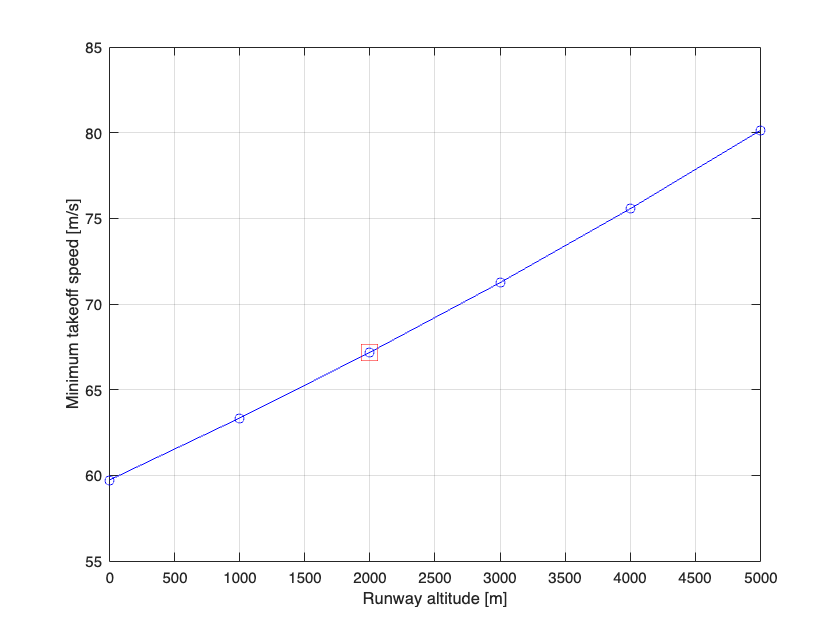

plot(hh(jj(end)), vmin_full(jj(end)), 'rs')
% Optional: repeat the legend command to prevent MATLAB from adding more
% entries
legend([p_empty p_full], 'Location', 'northwest')

To better illustrate, let's use small vectors for altitude and vmin

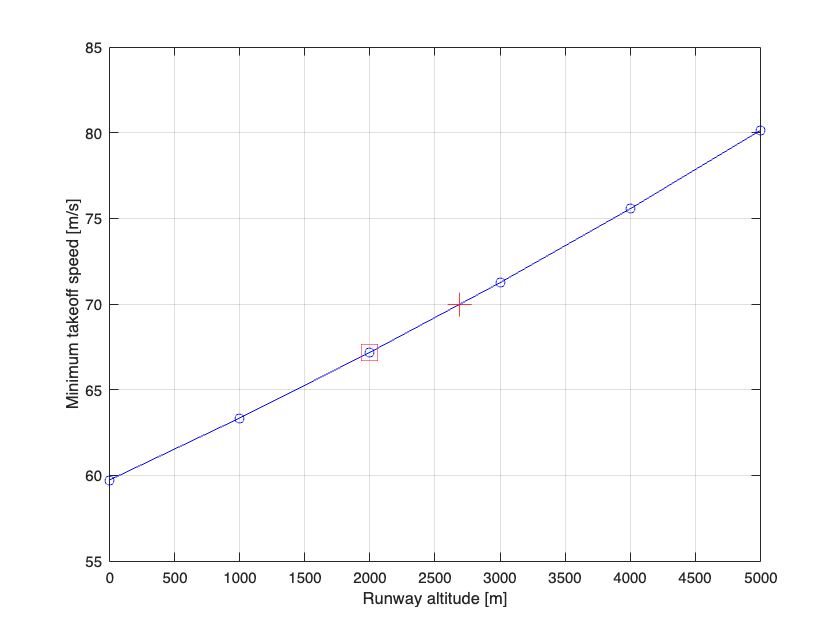

hh = linspace(0, 5000, 6)
vmin_empty = takeoff_speed(hh, 14500)
figure;
clf;

plot(hh,vmin_empty, 'bo-')
xlabel('Runway altitude [m]')
ylabel('Minimum takeoff speed [m/s]')
grid('on')

Find the values in the vmin vector that are less than or equal to 70

ii = find(vmin_empty <= 70)

The last value in that vector is

vmin_empty(ii(end))

and the corresponding runway altitude is

hh(ii(end))

Annotate the graph

hold on
plot(hh(ii(end)), vmin_empty(ii(end)), 'rs', 'MarkerSize',14)

## Interpolation

Repeat the above exercise using the `interp1` function instead of find to estimate the maximum runway altitudes with more precision.  Add a second marker on each line to visualize the interpolated points on the altitude vs. velocity axes. 

max_speed = 70;
h_max_empty = interp1(vmin_empty, hh, max_speed);
plot(h_max_empty, max_speed, 'r+', 'MarkerSize',16)
grid('on')
% max_speed = 90;
% h_max_full = interp1(vmin_full, hh, max_speed);
% plot(h_max_full, max_speed, 'rd');
% legend([p_empty p_full], 'Location', 'northwest')